When the simulation length is longer than approximately a month, the viewer does work properly. Here you can find an example of plotting the trajectories with MATLAB 3D plots.

area = 1;       % m2
ref = 1.5;      % NA
initMass = 10;  % kg
earthRadius = 6378136.3;    % m
[sma,ecc,inc,RAAN,aop,true_an] = deal(300000e3+earthRadius, 0.35, 25, 0, 100, 25);
startDate = juliandate(datetime('2024-01-30'));
burnOverride = -1;

Simulate the satellite.

tf = 1e8;
tic;
simOut = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.7432s


toc

Elapsed time is 3.946677 seconds.


tsSat = simOut.yout{1}.Values;
ttSat = timeseries2timetable(tsSat);
tsMoon = simOut.yout{5}.Values;
ttMoon = timeseries2timetable(tsMoon);
ttSat = retime(ttSat,'minutely');
ttMoon = retime(ttMoon,'minutely');

Plot the simulation in ICRF.

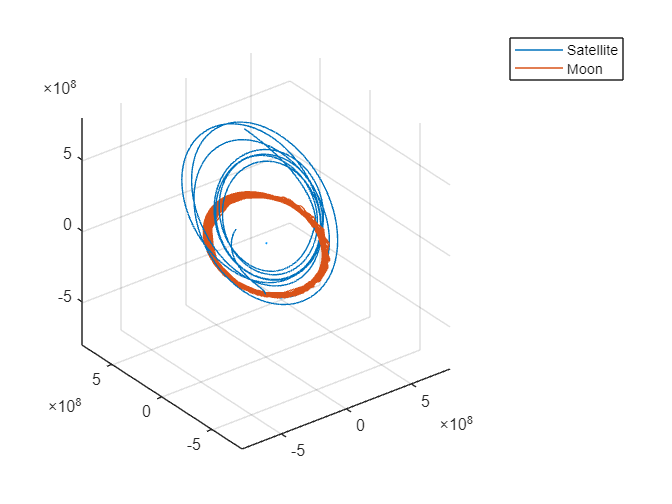

tic
figure
[X,Y,Z] = sphere();
p = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(p, 'edgecolor', 'none', 'FaceColor', [0,150,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSat.Data(:,1), ttSat.Data(:,2), ttSat.Data(:,3), DisplayName='Satellite')
plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), DisplayName='Moon')
legend
axis equal
daspect([1 1 1])
lim = [-8 8]*1e8;
xlim(lim)
ylim(lim)
zlim(lim)

toc

Elapsed time is 0.230202 seconds.
